% Define the data for lower limit, upper limit, and frequency
lowerLimits = [25,26,27,28,29,30,31,32,33,34,35]; 
upperLimits = [26,27,28,29,30,31,32,33,34,35,36]; 
frequencies = [25,70,210,275,430,550,340,130,90,55,25];  

% Create a table in MATLAB
dataTable = table(lowerLimits', upperLimits', frequencies',...
    'VariableNames', {'LowerLimit', 'UpperLimit', 'Frequency'});

% Display the table
disp(dataTable);

    LowerLimit    UpperLimit    Frequency
    __________    __________    _________

        25            26            25   
        26            27            70   
        27            28           210   
        28            29           275   
        29            30           430   
        30            31           550   
        31            32           340   
        32            33           130   
        33            34            90   
        34            35            55   
        35            36            25   




% Calculate mean, median, mode, and standard deviation
data = [];
for i = 1:length(lowerLimits)
    data = [data, ones(1, frequencies(i)) * ((upperLimits(i) + lowerLimits(i)) / 2)];
end

meanValue = mean(data);
medianValue = median(data);
modeValue = mode(data);
stdDeviation = std(data);

% Calculate empirical_mode, mode_shift, and Karl
empirical_mode = 3 * medianValue - 2 * meanValue;
mode_shift = modeValue - empirical_mode;
Karl = (meanValue - modeValue) / stdDeviation;

% Display the calculated statistics
fprintf('Mean: %.2f\n', meanValue);

Mean: 30.14


fprintf('Median: %.2f\n', medianValue);

Median: 30.50


fprintf('Mode: %.2f\n', modeValue);

Mode: 30.50


fprintf('Standard Deviation: %.2f\n', stdDeviation);

Standard Deviation: 1.91


fprintf('Empirical Mode: %.2f\n', empirical_mode);

Empirical Mode: 31.23


fprintf('Mode Shift: %.2f\n', mode_shift);

Mode Shift: -0.73


fprintf('Karl: %.2f\n', Karl);

Karl: -0.19


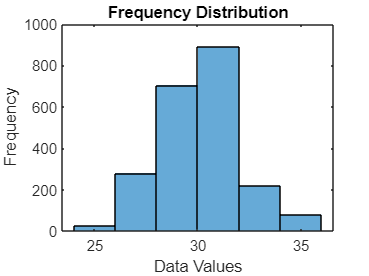


% Plotting the line graph
figure;
histogram(data, 'BinWidth', 2); % Change the 'BinWidth' according to your preference
title('Frequency Distribution');
xlabel('Data Values');
ylabel('Frequency');